# Tasks 1

## Loading up a dataset

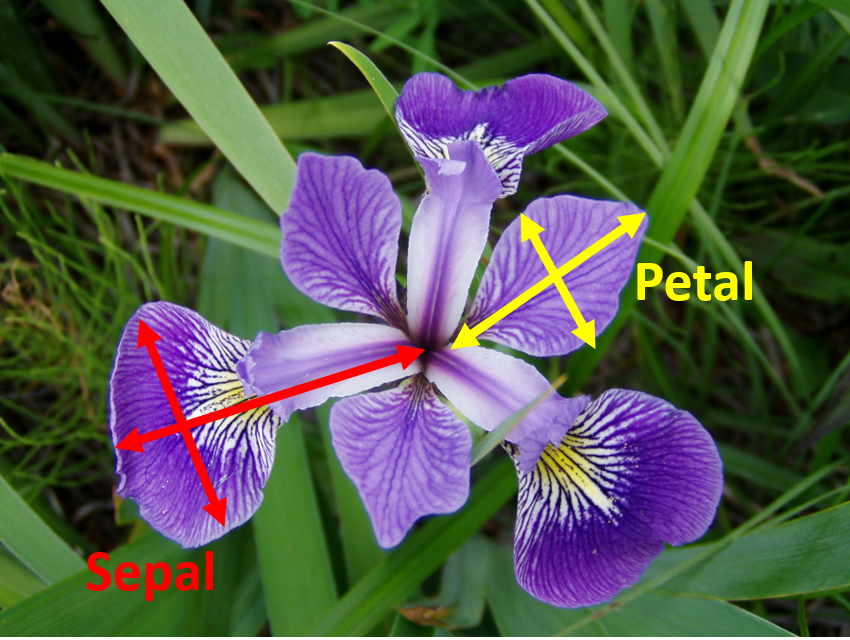

The iris.csv dataset (available on Moodle) contains petal and sepal measurements for 150 different irises belonging to three different species. You can assume the dataset is clean and ready for use in Machine Learning (ML) tasks. The challenge here is to use ML to predict which species an iris belongs to, based on its petal/sepal sizes. Load up the iris.csv file and echo out the contents of the first 10 rows of values

% load a dataset compiled by someone else:
mycellarray = readcell('iris.csv');

% first 10 rows of every column
mycellarray(1:1:10, 1:1:end)

ans = 10×5 cell array
    {'sepal_length'}    {'sepal_width'}    {'petal_length'}    {'petal_width'}    {'species'}
    {[      5.1000]}    {[     3.5000]}    {[      1.4000]}    {[     0.2000]}    {'setosa' }
    {[      4.9000]}    {[          3]}    {[      1.4000]}    {[     0.2000]}    {'setosa' }
    {[      4.7000]}    {[     3.2000]}    {[      1.3000]}    {[     0.2000]}    {'setosa' }
    {[      4.6000]}    {[     3.1000]}    {[      1.5000]}    {[     0.2000]}    {'setosa' }
    {[           5]}    {[     3.6000]}    {[      1.4000]}    {[     0.2000]}    {'setosa' }
    {[      5.4000]}    {[     3.9000]}    {[      1.7000]}    {[     0.4000]}    {'setosa' }
    {[      4.6000]}    {[     3.4000]}    {[      1.4000]}    {[     0.3000]}    {'setosa' }
    {[           5]}    {[     3.4000]}    {[      1.5000]}    {[     0.2000]}    {'setosa' }
    {[      4.4000]}    {[     2.9000]}    {[      1.4000]}    {[     0.2000]}    {'setosa' }


## Separating training and testing data

Shuffle the dataset and perform your horizontal split; use 60% for training data and 40% for testing data: 

(**Hint**: don't forget to delete the column titles before you start)

(**Sanity check**: your training data table should have a size of [90 5] and your testing data table should have a size of [60 5])

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

% deletes title row
mycellarray(1:1:1, :) = [];

% shuffle cell array
shuffle = mycellarray(randperm(size(mycellarray, 1)), :);

% 60% training / 40% testing data
tempTest = round(0.4 * size(shuffle,1));

%testData = shuffle(1:1:tempTest, :);
trainData = shuffle(tempTest+1:1:end, :);


## Separate class labels and examples

Separate out the 5th column, containing the class labels, from both your training data and your testing data.

(**Hint**: your class labels should become categorical arrays)

(**Hint**: your feature values should become numeric arrays)

% changes the cell array to a numerical array
label_index = 5;

% <my comment removed>:

testCategorical = categorical(testData(:, label_index));

Unrecognized function or variable 'testData'.

testData = cell2mat(testData(:, 1:end~=label_index));

% <my comment removed>:
trainCategorical = categorical(trainData(:, label_index));
trainData = cell2mat(trainData(:, 1:end~=label_index));


## Reading one example

Copy the first example in your training data into a variable called `temp`. Display the feature values in your copied example with a call to the `bar()` function.

(**Sanity check**: The result should be a bar graph with 4 bars.)

% temp var for the bar chart
temp = bar(trainData)    



## Training a k-NN classifier

Use your training data to train a k-NN classifier using k=1 nearest neighbour:

(**Sanity check**: k=1 is the default setting when you call `fitcknn()` without specifying any hyperparameters)

% comment
kNN = fitcknn(trainData,trainCategorical);



## Use your trained classifier for prediction

Use your trained classifier to predict labels for your testing data

% comment
predictions = predict(kNN,testData);


## Evaluating your classifier's performance

Generate a confusion matrix to summarise your classifier's performance, and use it to calculate the overall classification accuracy.

(**Sanity check**: you should expect an overall accuracy of 96.7%)

% write your code on the lines below
[c, order] = confusionmat(testCategorical, predictions);

confusionchart(testCategorical, predictions);

p = sum(diag(c)) / sum(c(1:1:end)) * 100

Check you can correctly interpret the values in the confusion matrix by completing the following questions. Use the sliders to select your answers:

(**Hint**: if you're unsure then it may help to use `confusionchart()` to display a graphical confusion matrix with labelling)

% how many setosa irises are there in the testing data?
15
% how many virginica irises are there in the testing data?
21
% how many of those virginica irises are correctly classified?
2

## Other classifiers

In lectures you've seen the syntax for training some other classifiers. This is easy to do and *it doesn't matter whether you actually understand how the classifiers work**. In reality, you'll often have to work with classifiers or algorithms that your don't *fully* understand from time to time. That's OK, and it's still important to be comfortable using a program like Matlab to train and evaluate their performance. Each of the classifiers below should be part of your "toolbox". The syntax for training them is very similar to the syntax for training a k-NN classifier, and the syntax for using them for prediction and evaluating their performance is identical.

* If you would like to understand more, then further readings are available in the table of classifiers shown in the second lecture (we will also return to learn more about neural networks in the final weeks of the unit).

Train and evaluate each of the following models using the irises data you prepared in the earlier tasks:

- A Naive Bayes classifier

- A Decision Tree classifier

- A Neural Network classifier

- A Support Vector Machine classifier


kNN = fitcknn(train_examples, train_labels , 'NumNeighbors', 3);
predictions = predict(kNN,test_examples);

[c, order] = confusionmat(test_labels, predictions);
p2 = sum(diag(c)) / sum(c(1:1:end)) * 100

knn_same = isequal(p2,p)


## No extension tasks yet

No extension tasks just yet, we're still learning... Move straight on to the next lab sheet once you've finished this one.